snpt

addpath myFunction\myftn\
gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 .4]);
f1.Visible = "on";

str = ["start"]

str = "start"

xl = xline([3 4],'ButtonDownFcn',@(src,event) start_drag(src,event))

xl =   2×1 ConstantLine array:

  ConstantLine
  ConstantLine


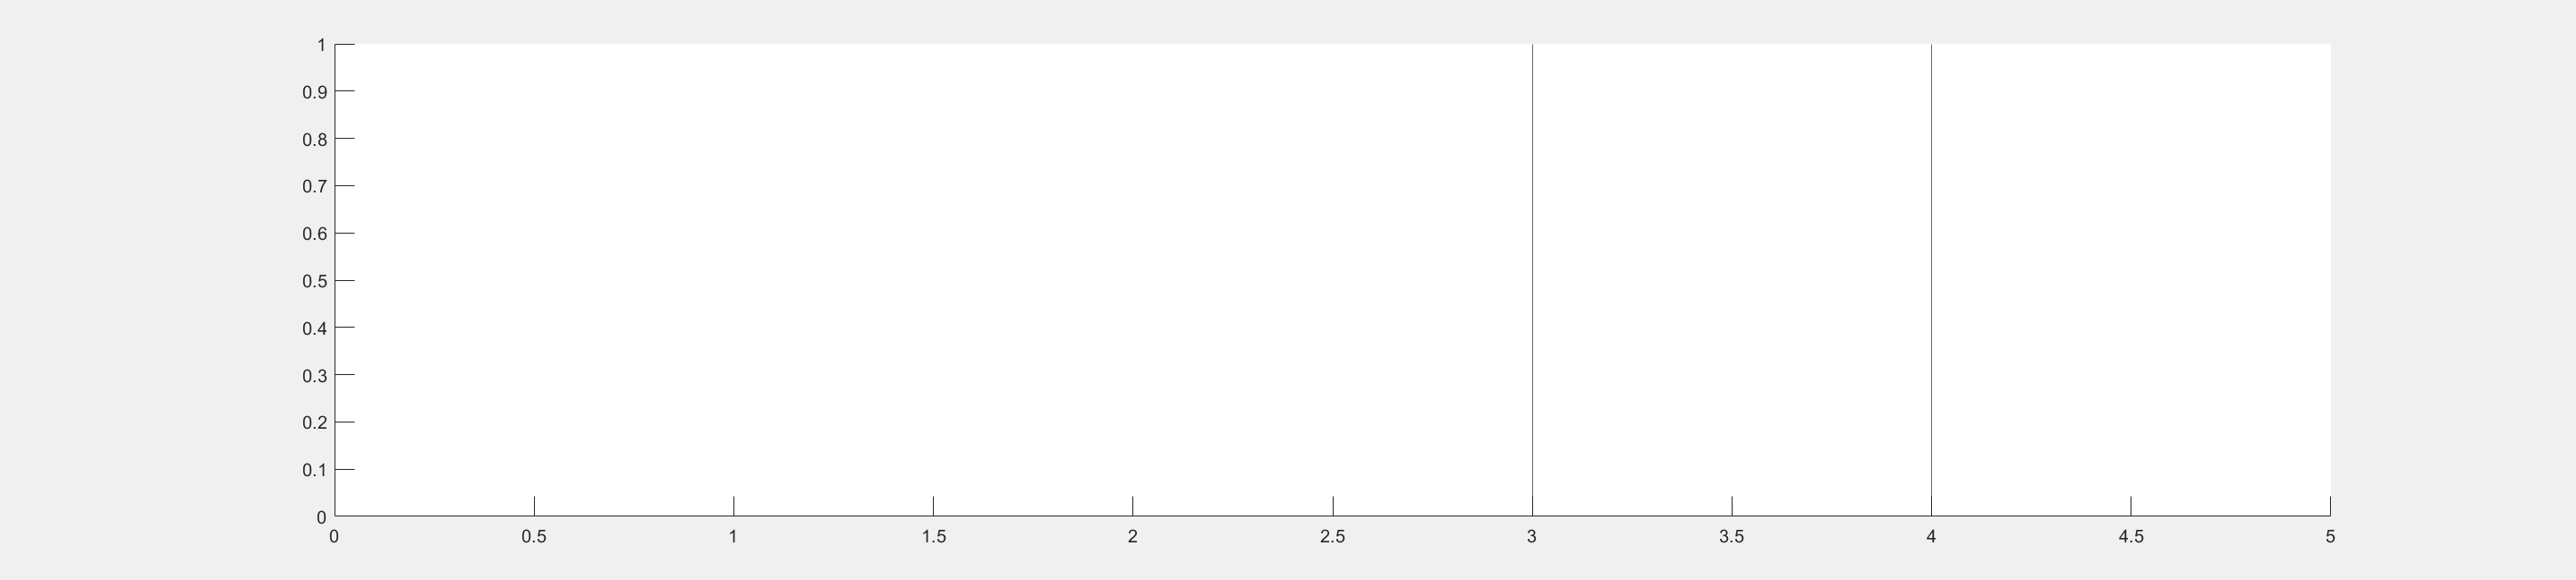

xlim([0 5])

set(f1,'WindowButtonUpFcn',@(src,event) stop_drag(src,event),...
    'WindowButtonMotionFcn', @(src,event) draging(src,event))
setappdata(f1,'is_dragging',false)
setappdata(f1,'drag_object',[])

function start_drag(src,event)
%src
%event
disp('start')
setappdata(gcf,'drag_object',src)
disp(src.Value)
% disp(getappdata(gcf,'drag_object'))
end


function stop_drag(src,event)
disp('stop')
setappdata(gcf,'drag_object',[])
%src
%event
end

function draging(src,event)
if ~isempty(getappdata(gcf,'drag_object'))
drag_object = getappdata(gcf,'drag_object');
cp = drag_object.Parent.CurrentPoint;
drag_object.Value =  cp(1);
end
% drag_object.Value =  cp(1);
% disp('stop')
%src
%event
% if getappdata(src,)
end